# Problem 3

interr = 'latex';
% interr = 'none';
set(groot,'defaulttextinterpreter',interr);  
set(groot, 'defaultAxesTickLabelInterpreter',interr);  
set(groot, 'defaultLegendInterpreter',interr);

## Preliminary Calculations and Constants:

Rm = 1738.2; % Lunar radius, km
mu = 4902.8005821478; % Lunar mu, km^3/s^2

## Part a)

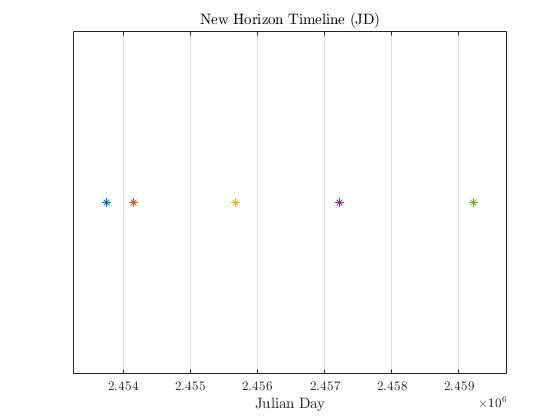

launch = 2453755.0000000;
Jupiter = 2454160.0000000;
Uranus = 2455670.0000000;
Pluto = 2457219.0000000;
UltimaThule = 2459216.0000000;
plot(launch,0,'*'),hold on,plot(Jupiter,0,'*'),plot(Uranus,0,'*'),plot(Pluto,0,'*'),plot(UltimaThule,0,'*')
grid on
xlabel('Julian Day')
% ylim([-.002 .002])
xlim([launch-500, UltimaThule+500])
title('New Horizon Timeline (JD)')
axis equal
set(gca,'ytick',[])

## Part b)

mu = 132712440017.99;
a1 = 149597898;
a2 = 5907150229;
[aT, eT, TOF_total, ...
    v1_0, gamma_1_N, v1_N, dv1, alpha1, beta1, ...
    v2_0, gamma_2_N, v2_N, dv2, alpha2, beta2, ...
    dv_mag_total] = coplanartransfer(a1,a2,0,pi,mu)

aT = 3.0284e+09

eT = 0.9506

TOF_total = 1.4372e+09

v1_0 =          0
   29.7847


gamma_1_N = 2.9802e-08

v1_N =     0.0000
   41.5985


dv1 =     0.0000
   11.8138


alpha1 = 1.0494e-07

beta1 = 3.1416

v2_0 =          0
    1.0535


gamma_2_N = 2.1073e-08

v2_N =          0
    4.7399


dv2 =          0
    3.6864


alpha2 = 2.7096e-08

beta2 = 3.1416

dv_mag_total = 15.5002

1/2 * (a1 + a2)

ans = 3.0284e+09

norm(dv1),norm(dv2)

ans = 11.8138

ans = 3.6864

TOF_jdyear = TOF_total/86400/365.25

TOF_jdyear = 45.5412

TOF_newhorz = (Pluto - launch)/365.25

TOF_newhorz = 9.4839

## Part c)

phase = pi - TOF_total * sqrt(mu/a2^3), phase_deg = rad2deg(phase)

phase = 1.9884

phase_deg = 113.9276

ts = 2*pi / (sqrt(mu/a1^3)-sqrt(mu/a2^3)), ts_day = ts/3600/24, ts_year = ts_day/365.25

ts = 3.1686e+07

ts_day = 366.7350

ts_year = 1.0041

## Part d)

e_pluto = 0.24885238;
rp_pluto = a2 * (1 - e_pluto)

rp_pluto = 4.4371e+09


[aTn, eTn, TOF_totaln, ...
    v1_0n, gamma_1_Nn, v1_Nn, dv1n, alpha1n, beta1n, ...
    v2_0n, gamma_2_Nn, v2_Nn, dv2n, alpha2n, beta2n, ...
    dv_mag_totaln] = coplanartransfer(a1,rp_pluto,0,pi,mu)

aTn = 2.2934e+09

eTn = 0.9348

TOF_totaln = 9.4712e+08

v1_0n =          0
   29.7847


gamma_1_Nn = 2.1073e-08

v1_Nn =     0.0000
   41.4293


dv1n =     0.0000
   11.6446


alpha1n = 7.4975e-08

beta1n = 3.1416

v2_0n =          0
    1.3968


gamma_2_Nn = 4.2147e-08

v2_Nn =          0
    5.4690


dv2n =          0
    4.0722


alpha2n = 5.6604e-08

beta2n = 3.1416

dv_mag_totaln = 15.7168

norm(dv1n)

ans = 11.6446

TOF_year = TOF_totaln/86400/365.25

TOF_year = 30.0124

TOF_jdyear - TOF_year

ans = 15.5288

### Function 1: Transfer Characteristics (Circle to Circle)

Can change to work with any starting and ending orbits, once that works, bi-elliptic/multiburn transfer can be done through recursion or multiple function calls

Transfer starting at periapsis of transfer orbit to transfer angle on orbit

a1 and a2 in km

ths1 and ths2 are initial and final true anomalies on transfer orbit

function [aT, eT, TOF_total, ...
    v1_0, gamma_1_N, v1_N, dv1, alpha1, beta1, ...
    v2_0, gamma_2_N, v2_N, dv2, alpha2, beta2, ...
    dv_mag_total] = coplanartransfer(a1,a2,ths1,ths2,mu)

Transfer Orbit Characteristics:

eT = (a2 - a1)/(a2 + a1 * cos(ths1));
aT = a2/(1+eT);
E1 = eccenAnom(ths1,eT);
E2 = eccenAnom(ths2,eT);
TOF1 = sqrt(aT^3/mu) * (E1 - eT*sin(E1));
TOF2 = sqrt(aT^3/mu) * (E2 - eT*sin(E2));
TOF_total = TOF2-TOF1;

1st Thrust Point Conditions (Pre-Maneuver: Initial Orbit): (change this to be able to accomodate other starting orbit)

r1_mag = a1; v1_mag_0 = sqrt(mu*(2/r1_mag-1/a1)); 
v1_0 = [0 v1_mag_0]';

1st Thrust Point Conditions (Post-Maneuver: Transfer Orbit):

v1_mag_N = sqrt(mu*(2/r1_mag - 1/aT));
gamma_1_N = findFPA(aT,eT,r1_mag,mu,ths1);
v1_N = v1_mag_N * [sin(gamma_1_N),cos(gamma_1_N)]';
dv1 = v1_N - v1_0; dv1_mag = norm(dv1);
[alpha1,beta1] = alphabeta(v1_mag_0,norm(v1_N),dv1_mag,gamma_1_N);

2nd Thrust Point Conditions (Pre-Maneuver: Transfer Orbit):

r2_mag = a2;
v2_mag_0 = sqrt(mu*(2/r2_mag - 1/aT)); v2_0 = [0 v2_mag_0]';

2nd Thrust Point Conditions (Post-Maneuver: Final Orbit): (change this to be able to accomodate other final orbit)

v2_mag_N = sqrt(mu*(2/r2_mag - 1/a2)); v2_N = [0 v2_mag_N]';
gamma_2_N = findFPA(aT,eT,r2_mag,mu,ths2);
dv2 = v2_N - v2_0; dv2_mag = norm(dv2);
dv_mag_total = dv1_mag + dv2_mag;
[alpha2,beta2] = alphabeta(v2_mag_0,norm(v2_N),dv2_mag,gamma_2_N);
end

### Function 2: Eccentric Anomaly 

function E = eccenAnom(ths,e)
    E = 2*atan(sqrt((1-e)/(1+e))*tan(ths/2));
end

### Function 3: Find FPA

function FPA = findFPA(a,e,r,mu,ths)
vmag = sqrt(mu*(2/r-1/a));
p = a*(1-e^2);
h = sqrt(mu*p);
FPA = acos(h/r/vmag);
if wrapTo2Pi(ths) <= 180
    FPA = abs(FPA);
else
    FPA = -abs(FPA);
end
end

### Function 4: Alpha and Beta

function [alpha, beta] = alphabeta(v0,vN,dv,dgamma)
angles = asin(vN/dv * sin(dgamma)); 
angles = [angles pi-angles];

if v0 > vN
    alpha = max(angles);
    beta = min(angles);
elseif v0 < vN
    alpha = min(angles);
    beta = max(angles);
elseif dv == 0
    alpha = 0;
    beta = pi;
end

if dgamma < 0
    alpha = -abs(alpha);
else
    alpha = abs(alpha);
end
end

### Function 5: Plotting Initial and Final Orbits

function plotinitfin(ai,ei,af,ef)
    ths_plot = linspace(0,2*pi,2^12)';
    ri = (ai*(1-ei^2))./(1+ei*cos(ths_plot));
    rf = (af*(1-ef^2))./(1+ef*cos(ths_plot));
    ri = ri .* [cos(ths_plot),sin(ths_plot)];
    rf = rf .* [cos(ths_plot),sin(ths_plot)];
    plot(ri(:,1),ri(:,2)), hold on, plot(rf(:,1),rf(:,2))
    grid on
    axis equal
    maxlim = max([ai af]); maxlim = [-maxlim maxlim]*1.5;
    xlim(maxlim), ylim(maxlim)
    plot(0,0,'go','MarkerSize', 10)
end

### Function 6: Plotting Transfer Orbit

function plottransfer(aT,eT,ths1,ths2)
ths_plot = linspace(ths1,ths2,2^12);
r_T_plot = aT * (1-eT^2)./(1+eT*cos(ths_plot));
rx_T = r_T_plot.*cos(ths_plot-ths1); ry_T = r_T_plot.*sin(ths_plot-ths1);
plot(rx_T,ry_T)
plot(r_T_plot(end).*cos(ths2-ths1),r_T_plot(end).*sin(ths2-ths1),'*')
end

### Function 7: Velocity Vectors

function plotvel(a,e,ths,v,color,dvoption,angle)
rmag = a*(1-e^2)/(1+e*cos(ths));
size = 3e3;
iCr = [cos(ths-angle) -sin(ths-angle); sin(ths-angle) cos(ths-angle)];
v = iCr*v;
if dvoption(1) == 1
    v0 = dvoption(2:3);
    v0 = iCr * v0;
    quiver(rmag*cos(ths-angle)+v0(1)*size,rmag*sin(ths-angle)+v0(2)*size,v(1),v(2),size,color) % dV
else
    quiver(rmag*cos(ths-angle),rmag*sin(ths-angle),v(1),v(2),size,color)
end
end

### Function 8: Position Vectors

function plotpos(a,e,ths,color,angle)
rmag = a*(1-e^2)/(1+e*cos(ths)); r = [rmag 0]';
iCr = [cos(ths-angle) -sin(ths-angle); sin(ths-angle) cos(ths-angle)];
r = iCr * r;
quiver(r(1),r(2),color,'Autoscale','off')
plotunit(r,ths-angle,color)
end

### Function 9: Unit Vectors

function plotunit(pos,th,color)
x = pos(1); y = pos(2); size = 7e3;
iCr = [cos(th) -sin(th); sin(th) cos(th)];
hat1 = iCr * [1 0]' * size;
hat2 = iCr * [0 1]' * size;
quiver(x,y,hat1(1),hat1(2),'r--')% x1
quiver(x,y,hat2(1),hat2(2),'r--')% x2
end

## Function 3: Find Direction Cosine Matrix

function iCr = findDCM(om,inc,th)
    col1 = [cos(om)*cos(th) - sin(om)*cos(inc)*sin(th);
        sin(om)*cos(th)+cos(om)*cos(inc)*sin(th);
        sin(inc)*sin(th)];
%     col2 = [-cos(om)*sin(th)-sin(om)*cos(inc)*cos(th);
%         -sin(om)*sin(th)+cos(om)*cos(inc)*cos(th);
%         sin(inc)*cos(th)];
    col3 = [sin(om)*sin(inc);
        -cos(om)*sin(inc);
        cos(inc)];
    
    col2 = cross(col3,col1);
    iCr = [col1 col2 col3];
end